[x,y] = dataset_generation(50, 4, 1.5, 10); %%Generate random dataset for linear regression

DRAW LEVEL SETS OF COST FUNCTION

f=@(m,b)(cost(x,y,m,b));
m = linspace(0,6, 100);
b = linspace(-20,20, 100);
[M,B] = meshgrid(m,b);
for l = 1: length(b)
    for k = 1 : length(m)    
        Z(l,k) = cost(x, y, m(k), b(l));
    end
end

figure;
contour(M,B,Z,[0 0.5 1 1.5 2 2.5 3 3.5 4 4.5 5 5.5]);
hold on

OPTIMIZATION:

[m,b] = rms_prop(x,y,0.999,0.01);

PROPAGATION POINTS:

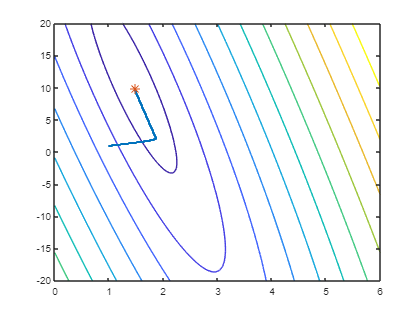

plot(m, b, '+', 'LineWidth', 1, 'MarkerSize', 2)
hold on
plot(m(end), b(end), '*', 'LineWidth', 1, 'MarkerSize', 10)

THE PREDICTED m AND b PARAMETERS

m(end)

ans = 1.4811

b(end)

ans = 9.7904

DATA POINTS AND PREDICTED LINE 

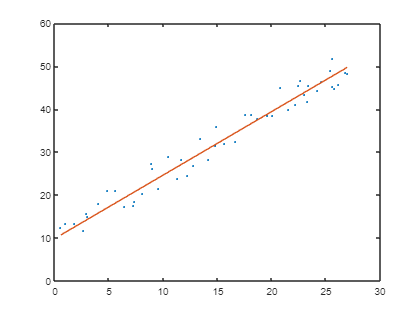

figure;
stem(x,y,'LineStyle','none','Marker','.');
hold on;
z = m(end)*x+b(end);
plot(x,z);